clear
load retea3

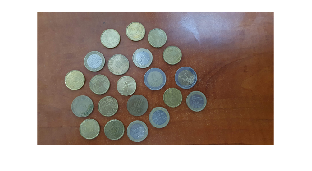

% Read the image
originalImage = imread('monede2.jpg');
originalImage = imresize(originalImage,0.13);
imshow(originalImage);

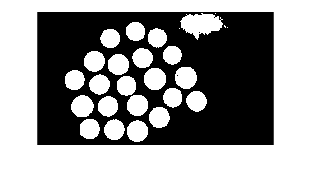

grayImage = createMask(originalImage);
imshow(grayImage)

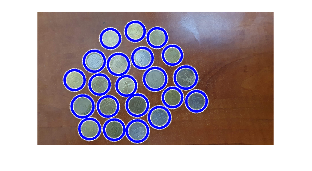

% Detect circles (coins) using Hough transform
[centers, radii] = imfindcircles(grayImage, [15, 90], 'Sensitivity', 0.8);

% Display the detected circles on the original image
figure;
imshow(originalImage);
viscircles(centers, radii, 'EdgeColor', 'b');

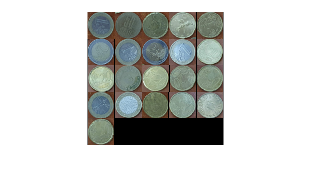

% Extract individual coins using circle information
numCoins = length(radii);
coinImages = cell(1, numCoins);

targetSize = [224, 224]; % Adjust the target size as needed

for k = 1:numCoins
    % Extract the k-th coin region based on circle information
    centerX = centers(k, 1);
    centerY = centers(k, 2);
    radius = radii(k);
    
    % Define region of interest (ROI) for each coin
    coinImages{k} = imcrop(originalImage, [centerX - radius, centerY - radius, 2 * radius, 2 * radius]);
    resizedImage = imresize(coinImages{k}, targetSize);

end
montage(coinImages, 'Size', [NaN, 5]); % Adjust the number of columns (5 in this example)

numCoins = length(radii);
coinLabels = cell(1, numCoins);

count50Bani = 0;

for k = 1:numCoins
    % Extract the k-th coin region based on circle information
    centerX = centers(k, 1);
    centerY = centers(k, 2);
    radius = radii(k);
    
    % Define region of interest (ROI) for each coin
    coinROI = imcrop(originalImage, [centerX - radius, centerY - radius, 2 * radius, 2 * radius]);
    resizedCoin = imresize(coinROI, targetSize);

    % Classify the coin using the trained network
    coinLabels{k} = classify(trainedNet, resizedCoin);
    
    if strcmp(char(coinLabels{k}), '50Bani')
        count50Bani = count50Bani + 1;
    end

    % Write classification label next to the coin on the original image
    positionX = max(1, centerX - radius);
    positionY = max(1, centerY - radius - 20); % Adjust this value for label position
    originalImage = insertText(originalImage, [positionX, positionY], char(coinLabels{k}), 'FontSize', 12, 'BoxColor', 'white', 'TextColor', 'black');
end
    

totalLei = count50Bani * 50 / 100

totalLei = 1.5000

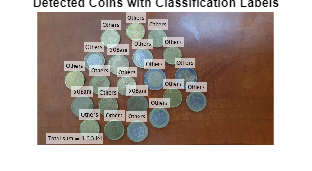


positionX = 20;
positionY = 270;
textStr = sprintf('Total sum = %.2f lei', totalLei);
originalImage = insertText(originalImage, [positionX, positionY], textStr, 'FontSize', 12, 'BoxColor', 'white', 'TextColor', 'black');

% Show the original image with detected circles and classified coins
figure;
imshow(originalImage);
title('Detected Coins with Classification Labels');